syms K tau s t x c

data = readtable("C:\Users\spoka\OneDrive - Olin College of Engineering\Desktop\Olin\0 Semester 4\ESA\Final Project\slower_calibration.csv"); %this path is hardcoded to the one on my computer
left_wheel = data.Var1;
right_wheel = data.Var2;
t = linspace(0,3,141);
%cftool

M(s) = (K/tau)/(s+1/tau)*1/s

$$M(s) = \frac{K}{s\,\tau \,\left(s+\frac{1}{\tau }\right)}$$

mt = ilaplace(M(s))

$$mt = K-K\,{\mathrm{e}}^{-\frac{t}{\tau }}$$

% we are doing a small movemean on the motor data because otherwise the fit tool doesn't work
mmean = 3;
mmr = movmean(right_wheel,mmean);
%plot the fit
clf; hold on;
plot(t,right_wheel,"b-","DisplayName","Raw Wheel Data") % plot the raw wheel data
plot(t,mmr,"r--","DisplayName","Move Mean Wheel Data") % plot the movemean wheel data
Fit1 = fit(t',mmr,@(K,tau,x) K*(1-exp(-x/tau))) % fit is calculated here

Fit1 =      General model:
     Fit1(x) = K*(1-exp(-x/tau))
     Coefficients (with 95% confidence bounds):
       K =      0.4098  (0.4086, 0.411)
       tau =     0.09581  (0.09283, 0.09879)

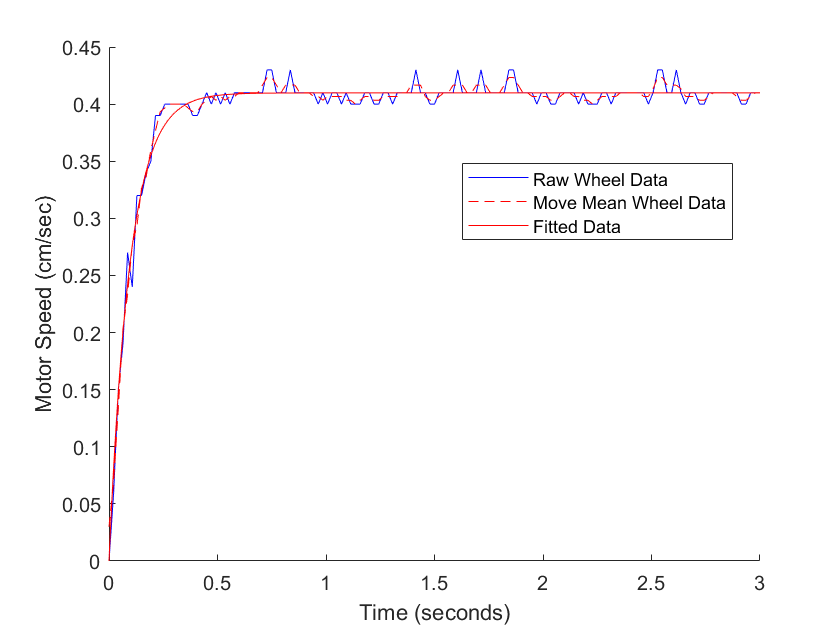

plot(Fit1) %plot fit
xlim([0,3])
legend(["Raw Wheel Data","Move Mean Wheel Data","Fitted Data"],"location","best")
xlabel("Time (seconds)"); ylabel("Motor Speed (cm/sec)")

Actual_K = Fit1.K*150 %fit of K times the unit step value, which for us was 150

Actual_K = 61.4715